### Set up workspace for Year 7

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 0 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')
% Casts 
cast01u = readSBScnv( 'uar46_001.cnv' );
cast02u = readSBScnv( 'uar46_002.cnv' );
cast03u = readSBScnv( 'uar46_003.cnv' );
cast04u = readSBScnv( 'uar46_004.cnv' );
cast05u = readSBScnv( 'uar46_005.cnv' );
cast06u = readSBScnv( 'uar46_006.cnv' );
cast07u = readSBScnv( 'uar46_007.cnv' );
cast08u = readSBScnv( 'uar46_008.cnv' );
cast09u = readSBScnv( 'uar46_009.cnv' );
cast10u = readSBScnv( 'uar46_010.cnv' );
cast11u = readSBScnv( 'uar46_011.cnv' );
cast12u = readSBScnv( 'uar46_012.cnv' );
cast13u = readSBScnv( 'uar46_013.cnv' );
cast14u = readSBScnv( 'uar46_014.cnv' );
cast15u = readSBScnv( 'uar46_015.cnv' );
cast16u = readSBScnv( 'uar46_016.cnv' );
cast17u = readSBScnv( 'uar46_017.cnv' );
cast18u = readSBScnv( 'uar46_018.cnv' );
cast19u = readSBScnv( 'uar46_019.cnv' );

cast01d = readSBScnv( 'dar46_001.cnv' );
cast02d = readSBScnv( 'dar46_002.cnv' );
cast03d = readSBScnv( 'dar46_003.cnv' );
cast04d = readSBScnv( 'dar46_004.cnv' );
cast05d = readSBScnv( 'dar46_005.cnv' );
cast06d = readSBScnv( 'dar46_006.cnv' );
cast07d = readSBScnv( 'dar46_007.cnv' );
cast08d = readSBScnv( 'dar46_008.cnv' );
cast09d = readSBScnv( 'dar46_009.cnv' );
cast10d = readSBScnv( 'dar46_010.cnv' );
cast11d = readSBScnv( 'dar46_011.cnv' );
cast12d = readSBScnv( 'dar46_012.cnv' );
cast13d = readSBScnv( 'dar46_013.cnv' );
cast14d = readSBScnv( 'dar46_014.cnv' );
cast15d = readSBScnv( 'dar46_015.cnv' );
cast16d = readSBScnv( 'dar46_016.cnv' );
cast17d = readSBScnv( 'dar46_017.cnv' );
cast18d = readSBScnv( 'dar46_018.cnv' );
cast19d = readSBScnv( 'dar46_019.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7\Final_From_Leah')
load ar46_final.mat

% Combine leah's finalized product with my oxygen file
% function [cast,cast0] = combine_CTD_files_Aanderaa_Yr7(leah_cast,cast)
[cast01u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_001u,cast01u); [cast01d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_001d,cast01d); 
[cast02u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_002u,cast02u); [cast02d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_002d,cast02d); 
[cast03u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_003u,cast03u); [cast03d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_003d,cast03d);  
[cast04u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_004u,cast04u); [cast04d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_004d,cast04d);  
[cast05u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_005u,cast05u); [cast05d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_005d,cast05d);  
[cast06u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_006u,cast06u); [cast06d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_006d,cast06d);  
[cast07u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_007u,cast07u); [cast07d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_007d,cast07d);  
[cast08u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_008u,cast08u); [cast08d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_008d,cast08d);  
[cast09u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_009u,cast09u); [cast09d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_009d,cast09d);  
[cast10u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_010u,cast10u); [cast10d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_010d,cast10d);  
[cast11u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_011u,cast11u); [cast11d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_011d,cast11d);  
[cast12u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_012u,cast12u); [cast12d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_012d,cast12d);  
[cast13u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_013u,cast13u); [cast13d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_013d,cast13d);
[cast14u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_014u,cast14u); [cast14d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_014d,cast14d);
[cast15u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_015u,cast15u); [cast15d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_015d,cast15d);
[cast16u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_016u,cast16u); [cast16d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_016d,cast16d);
[cast17u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_017u,cast17u); [cast17d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_017d,cast17d);
[cast18u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_018u,cast18u); [cast18d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_018d,cast18d);
[cast19u, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_019u,cast19u); [cast19d, ~] = combine_CTD_files_Aanderaa_Yr7(ar46_019d,cast19d);

### Create bottle summary file with Leah's calibrated bottle file

% %     cast.CTDcal(:) = {'True'};
% %     cast.CTDcal = string(cast.CTDcal);
% addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year7')
% addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7\Final_From_Leah')
% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')
% 
% btl = readtable('Irminger_Sea-06_ar46-05_Discrete_Summary_KF.xlsx','TextType','string');
% btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
% btl.Winkler_mLL = double(btl.Winkler_mLL);
% btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);
% 
% btlsum11 = btl(btl.Cast == 11,:);
% btlsum12 = btl(btl.Cast == 12,:);
% btlsum13 = btl(btl.Cast == 13,:);
% 
% btlsum11 = combine_btl_files_Aanderaa_Yr7('ar46-05_011.cbot_so','ar46-05011.csv',btlsum11);
% btlsum12 = combine_btl_files_Aanderaa_Yr7('ar46-05_012.cbot_so','ar46-05012.csv',btlsum12);
% btlsum13 = combine_btl_files_Aanderaa_Yr7('ar46-05_013.cbot_so','ar46-05013.csv',btlsum13);

### Combine cast and bottle files with Leah's final product. Clean up and organize variables into tables. 

CTD_sen1 = 1;
CTD_sen2 = 2; 

% [castu, castd, btlsum] = Process_Cast_Aanderaa(castu,castd,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast01u, cast01d, btlsum01] = Process_Cast_Aanderaa(cast01u,cast01d,0,CTD_sen1,'Cast 01');
[cast02u, cast02d, btlsum02] = Process_Cast_Aanderaa(cast02u,cast02d,0,CTD_sen1,'Cast 02');
[cast03u, cast03d, btlsum03] = Process_Cast_Aanderaa(cast03u,cast03d,0,CTD_sen1,'Cast 03');
[cast04u, cast04d, btlsum04] = Process_Cast_Aanderaa(cast04u,cast04d,0,CTD_sen1,'Cast 04');
[cast05u, cast05d, btlsum05] = Process_Cast_Aanderaa(cast05u,cast05d,0,CTD_sen1,'Cast 05');
[cast06u, cast06d, btlsum06] = Process_Cast_Aanderaa(cast06u,cast06d,0,CTD_sen1,'Cast 06');
[cast07u, cast07d, btlsum07] = Process_Cast_Aanderaa(cast07u,cast07d,0,CTD_sen1,'Cast 07');
[cast08u, cast08d, btlsum08] = Process_Cast_Aanderaa(cast08u,cast08d,0,CTD_sen1,'Cast 08');
[cast09u, cast09d, btlsum09] = Process_Cast_Aanderaa(cast09u,cast09d,0,CTD_sen1,'Cast 09');
[cast10u, cast10d, btlsum10] = Process_Cast_Aanderaa(cast10u,cast10d,0,CTD_sen1,'Cast 10'); 
[cast11u, cast11d, btlsum11] = Process_Cast_Aanderaa(cast11u,cast11d,0,CTD_sen1,'Cast 11');
[cast12u, cast12d, btlsum12] = Process_Cast_Aanderaa(cast12u,cast12d,0,CTD_sen2,'Cast 12');
[cast13u, cast13d, btlsum13] = Process_Cast_Aanderaa(cast13u,cast13d,0,CTD_sen2,'Cast 13');
[cast14u, cast14d, btlsum14] = Process_Cast_Aanderaa(cast14u,cast14d,0,CTD_sen2,'Cast 14');
[cast15u, cast15d, btlsum15] = Process_Cast_Aanderaa(cast15u,cast15d,0,CTD_sen2,'Cast 15');
[cast16u, cast16d, btlsum16] = Process_Cast_Aanderaa(cast16u,cast16d,0,CTD_sen2,'Cast 16');
[cast17u, cast17d, btlsum17] = Process_Cast_Aanderaa(cast17u,cast17d,0,CTD_sen2,'Cast 17');
[cast18u, cast18d, btlsum18] = Process_Cast_Aanderaa(cast18u,cast18d,0,CTD_sen1,'Cast 18');
[cast19u, cast19d, btlsum19] = Process_Cast_Aanderaa(cast19u,cast19d,0,CTD_sen1,'Cast 19');

### Calculate and apply time lag for Aanderaa optode 

Calculated in depth space because RMSDs lower than by calculating in density space 

% Shallower than 1000 m casts uncommented   
% [ Gordon2020_01] = Aanderaa_timelag_Yr7(cast01d,cast01u,[1000 2000]);
% [ Gordon2020_02] = Aanderaa_timelag_Yr7(cast02d,cast02u,[1000 2000]);
% [ Gordon2020_03] = Aanderaa_timelag_Yr7(cast03d,cast03u,[1000 2000]);
[ Gordon2020_04] = Aanderaa_timelag_Yr7(cast04d,cast04u,[1000 2000]);
% [ Gordon2020_05] = Aanderaa_timelag_Yr7(cast05d,cast05u,[1000 2000]);
% [ Gordon2020_06] = Aanderaa_timelag_Yr7(cast06d,cast06u,[1000 2000]);
[ Gordon2020_07] = Aanderaa_timelag_Yr7(cast07d,cast07u,[1000 2000]);
[ Gordon2020_08] = Aanderaa_timelag_Yr7(cast08d,cast08u,[1000 2000]);
[ Gordon2020_09] = Aanderaa_timelag_Yr7(cast09d,cast09u,[1000 2000]);
[ Gordon2020_10] = Aanderaa_timelag_Yr7(cast10d,cast10u,[1000 2000]);
[ Gordon2020_11] = Aanderaa_timelag_Yr7(cast11d,cast11u,[1000 2000]);
[ Gordon2020_12] = Aanderaa_timelag_Yr7(cast12d,cast12u,[1000 2000]);
[ Gordon2020_13] = Aanderaa_timelag_Yr7(cast13d,cast13u,[1000 2000]);
[ Gordon2020_14] = Aanderaa_timelag_Yr7(cast14d,cast14u,[1000 2000]);
[ Gordon2020_15] = Aanderaa_timelag_Yr7(cast15d,cast15u,[1000 2000]);
[ Gordon2020_16] = Aanderaa_timelag_Yr7(cast16d,cast16u,[1000 2000]);
[ Gordon2020_17] = Aanderaa_timelag_Yr7(cast17d,cast17u,[1000 2000]);
% [ Gordon2020_18] = Aanderaa_timelag_Yr7(cast18d,cast18u,[1000 2000]);
[ Gordon2020_19] = Aanderaa_timelag_Yr7(cast19d,cast19u,[1000 2000]);

thickness1 = [Gordon2020_04.thickness1
Gordon2020_07.thickness1
Gordon2020_08.thickness1
Gordon2020_09.thickness1
Gordon2020_10.thickness1
Gordon2020_11.thickness1
Gordon2020_12.thickness1
Gordon2020_13.thickness1
% Gordon2020_14.thickness1
Gordon2020_15.thickness1
Gordon2020_16.thickness1
Gordon2020_17.thickness1
Gordon2020_19.thickness1];

thickness2 = [Gordon2020_04.thickness2    
Gordon2020_07.thickness2
Gordon2020_08.thickness2
Gordon2020_09.thickness2
Gordon2020_10.thickness2
Gordon2020_11.thickness2
Gordon2020_12.thickness2
Gordon2020_13.thickness2
% Gordon2020_14.thickness2
Gordon2020_15.thickness2
Gordon2020_16.thickness2
Gordon2020_17.thickness2
Gordon2020_19.thickness2];

thickness = [thickness1 thickness2]

thickness =     49    47
     0    38
     0    18
     0    26
    35    36
    32    30
    21    22
    21    24
    38    36
    40    42


mean(thickness)

ans =    26.4167   33.0833


median(thickness)

ans =    33.5000   34.5000


std(thickness)

ans =    17.8960    9.2879


tau_Tref1 = [Gordon2020_04.tau_Tref1    
Gordon2020_07.tau_Tref1
Gordon2020_08.tau_Tref1
Gordon2020_09.tau_Tref1
Gordon2020_10.tau_Tref1
Gordon2020_11.tau_Tref1
Gordon2020_12.tau_Tref1
Gordon2020_13.tau_Tref1
% Gordon2020_14.tau_Tref1
Gordon2020_15.tau_Tref1
Gordon2020_16.tau_Tref1
Gordon2020_17.tau_Tref1
Gordon2020_19.tau_Tref1];

tau_Tref2 = [Gordon2020_04.tau_Tref2    
Gordon2020_07.tau_Tref2
Gordon2020_08.tau_Tref2
Gordon2020_09.tau_Tref2
Gordon2020_10.tau_Tref2
Gordon2020_11.tau_Tref2
Gordon2020_12.tau_Tref2
Gordon2020_13.tau_Tref2
% Gordon2020_14.tau_Tref2
Gordon2020_15.tau_Tref2
Gordon2020_16.tau_Tref2
Gordon2020_17.tau_Tref2
Gordon2020_19.tau_Tref2];

tau_Tref = [tau_Tref1 tau_Tref2] 

tau_Tref =    28.4042   27.3381
    2.9249   22.5590
    2.9249   12.0537
    2.9249   16.2357
   20.9729   21.5011
   19.3902   18.3372
   13.6187   14.1410
   13.6187   15.1875
   22.5590   21.5011
   23.6183   24.6792


tau_Tref1(5:end) = NaN;
nanmean(tau_Tref)

ans =    16.5610   19.9771


nanmedian(tau_Tref)

ans =    20.1816   20.7093


nanstd(tau_Tref)

ans =     9.2804    4.8964


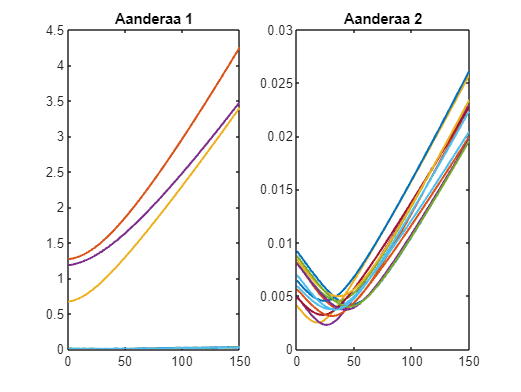


rmsd1 = [Gordon2020_04.rmsd1    
Gordon2020_07.rmsd1
Gordon2020_08.rmsd1
Gordon2020_09.rmsd1
Gordon2020_10.rmsd1
Gordon2020_11.rmsd1
Gordon2020_12.rmsd1
Gordon2020_13.rmsd1
Gordon2020_14.rmsd1
Gordon2020_15.rmsd1
Gordon2020_16.rmsd1
Gordon2020_17.rmsd1
Gordon2020_19.rmsd1];

rmsd2 = [Gordon2020_04.rmsd2    
Gordon2020_07.rmsd2
Gordon2020_08.rmsd2
Gordon2020_09.rmsd2
Gordon2020_10.rmsd2
Gordon2020_11.rmsd2
Gordon2020_12.rmsd2
Gordon2020_13.rmsd2
Gordon2020_14.rmsd2
Gordon2020_15.rmsd2
Gordon2020_16.rmsd2
Gordon2020_17.rmsd2
Gordon2020_19.rmsd2];

figure
subplot(1,2,1)
plot(Gordon2020_04.thickness_constants1,rmsd1,'Linewidth',1.4)
title('Aanderaa 1')

subplot(1,2,2)
plot(Gordon2020_04.thickness_constants2,rmsd2,'Linewidth',1.4)
title('Aanderaa 2')

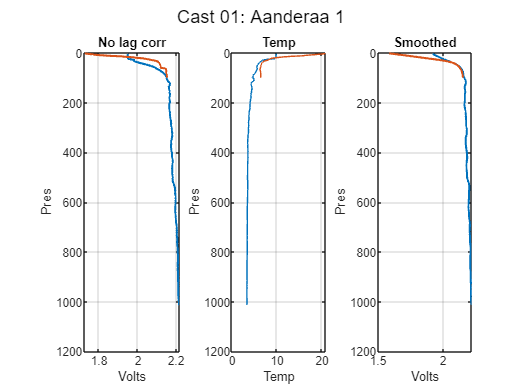

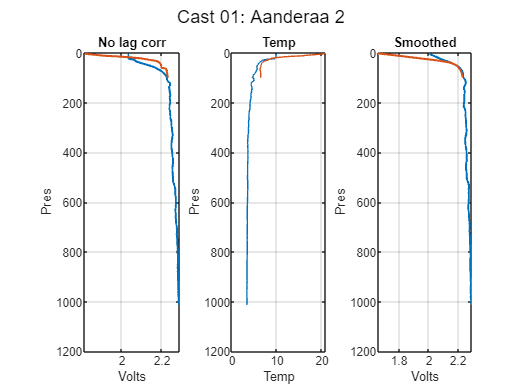

tau.thickness1 = 34; tau.thickness2 = 35; 
% tau.thickness = 10.2; 
% tau.tau_Tref = 4;
[cast01d, cast01u] = correct_Aanderaa_profiles_Yr7(cast03d,cast01u,tau,'Cast 01');

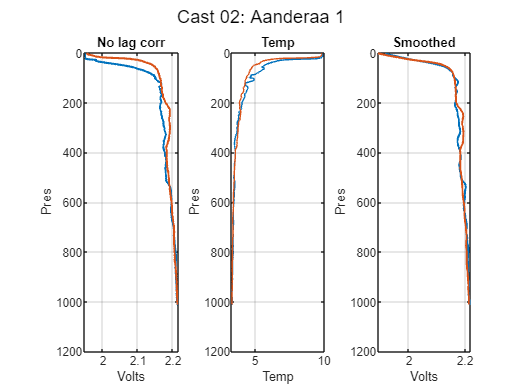

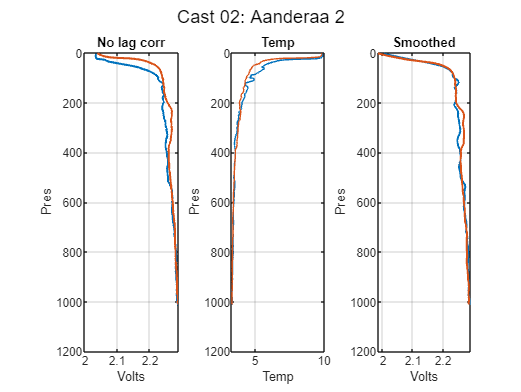

[cast02d, cast02u] = correct_Aanderaa_profiles_Yr7(cast03d,cast02u,tau,'Cast 02');

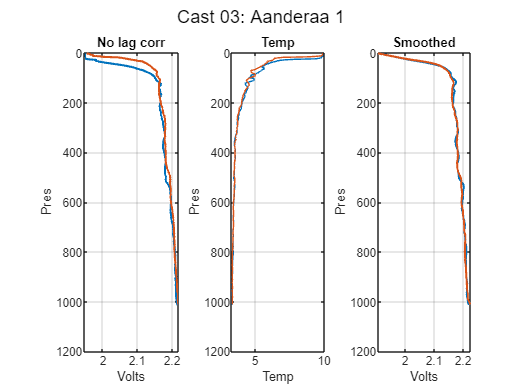

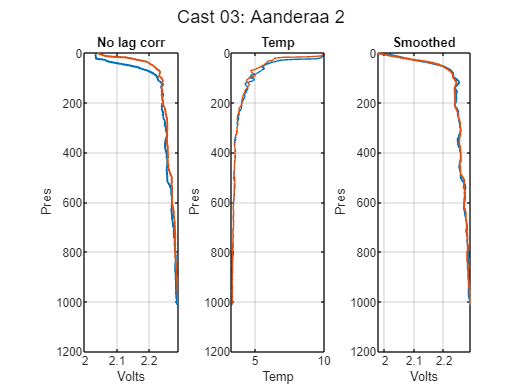

[cast03d, cast03u] = correct_Aanderaa_profiles_Yr7(cast03d,cast03u,tau,'Cast 03');

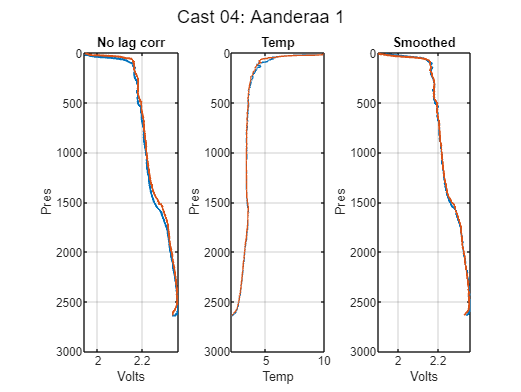

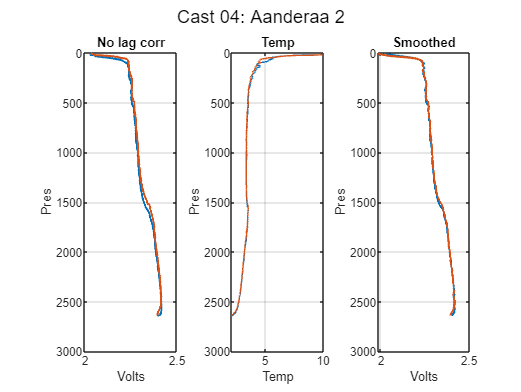

[cast04d, cast04u] = correct_Aanderaa_profiles_Yr7(cast04d,cast04u,tau,'Cast 04');

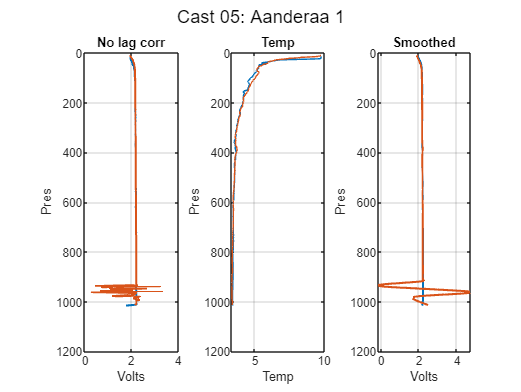

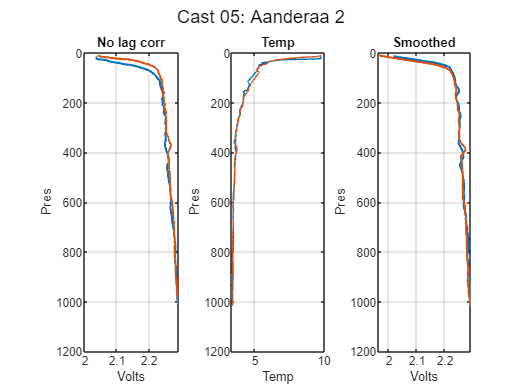

[cast05d, cast05u] = correct_Aanderaa_profiles_Yr7(cast05d,cast05u,tau,'Cast 05');

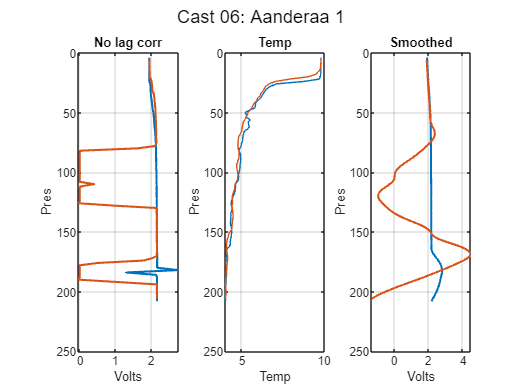

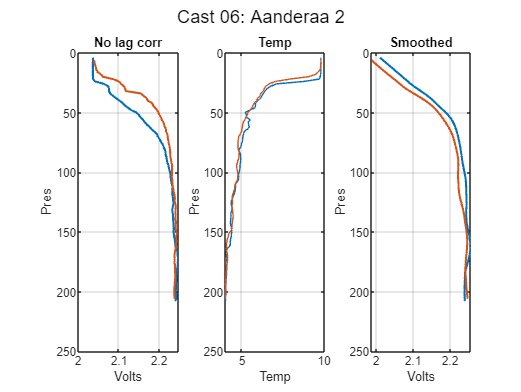

[cast06d, cast06u] = correct_Aanderaa_profiles_Yr7(cast06d,cast06u,tau,'Cast 06');

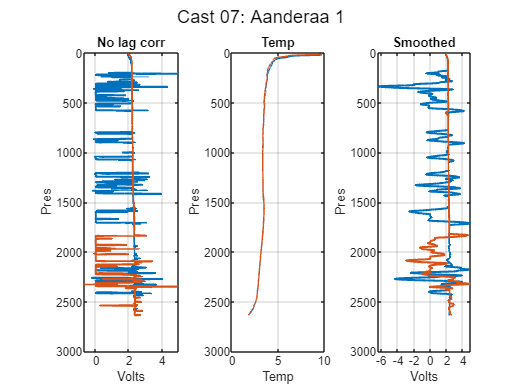

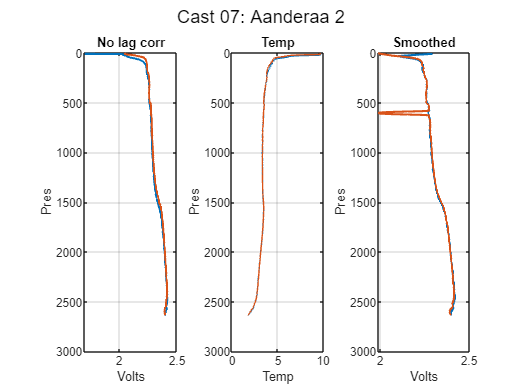

[cast07d, cast07u] = correct_Aanderaa_profiles_Yr7(cast07d,cast07u,tau,'Cast 07');

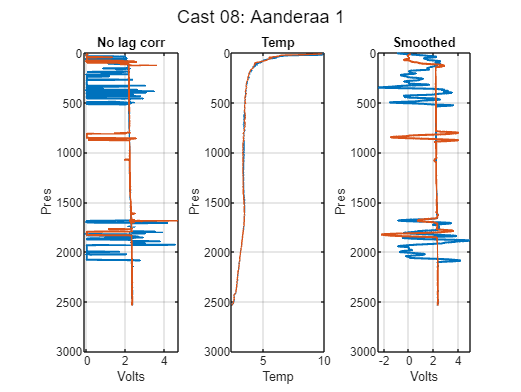

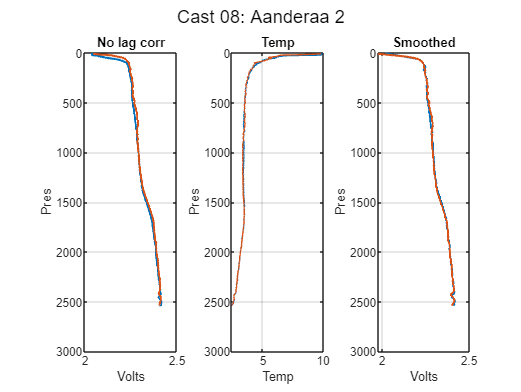

[cast08d, cast08u] = correct_Aanderaa_profiles_Yr7(cast08d,cast08u,tau,'Cast 08');

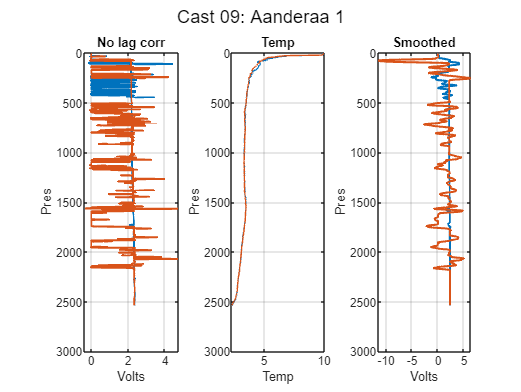

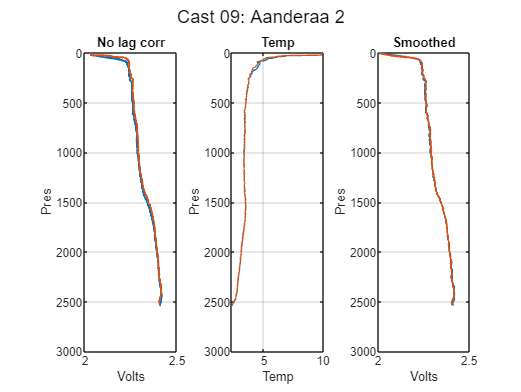

[cast09d, cast09u] = correct_Aanderaa_profiles_Yr7(cast09d,cast09u,tau,'Cast 09');

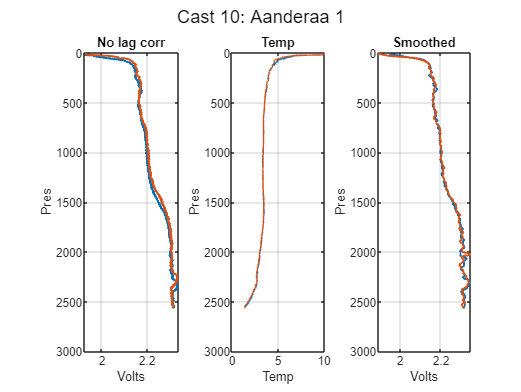

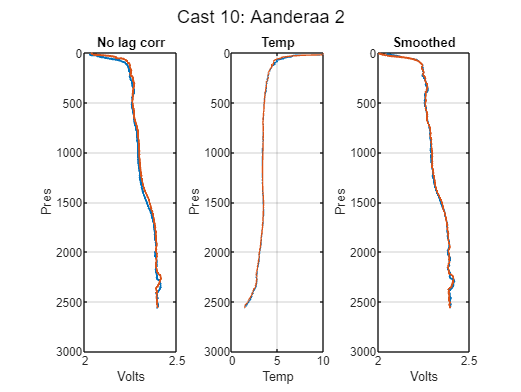

[cast10d, cast10u] = correct_Aanderaa_profiles_Yr7(cast10d,cast10u,tau,'Cast 10');

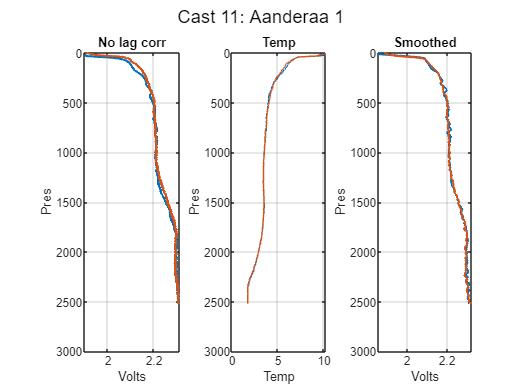

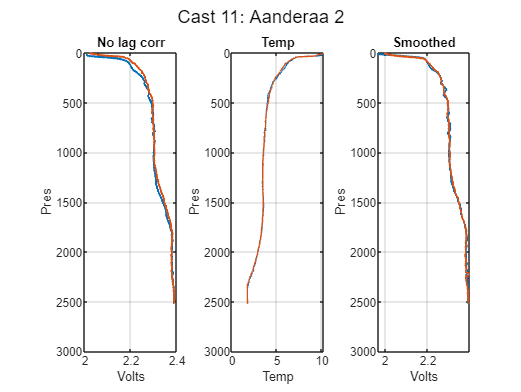

[cast11d, cast11u] = correct_Aanderaa_profiles_Yr7(cast11d,cast11u,tau,'Cast 11');

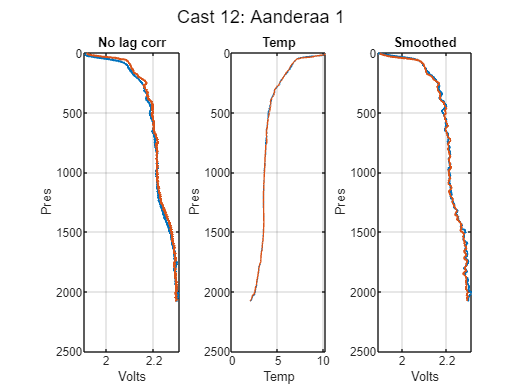

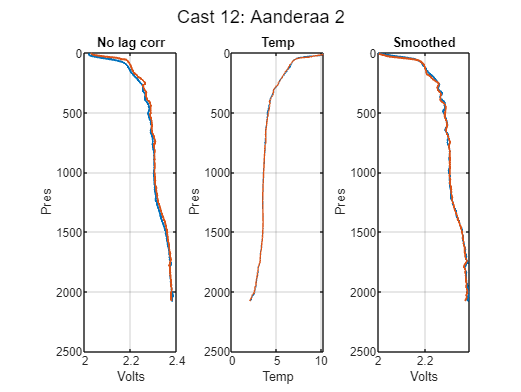

[cast12d, cast12u] = correct_Aanderaa_profiles_Yr7(cast12d,cast12u,tau,'Cast 12');

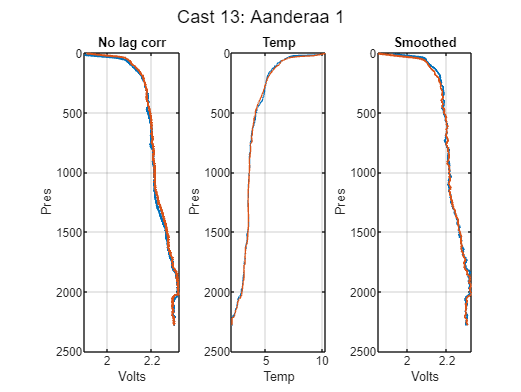

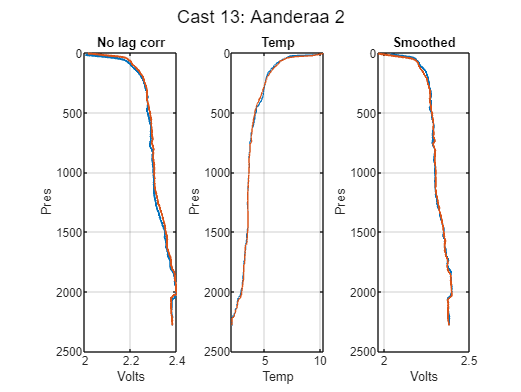

[cast13d, cast13u] = correct_Aanderaa_profiles_Yr7(cast13d,cast13u,tau,'Cast 13');

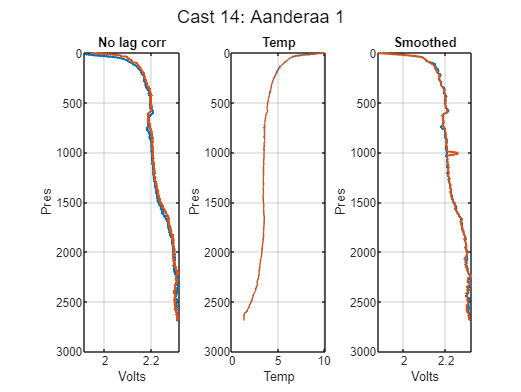

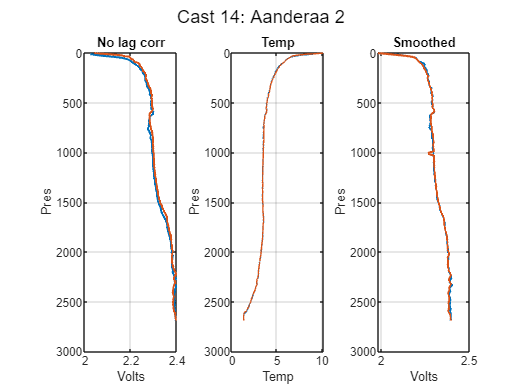

[cast14d, cast14u] = correct_Aanderaa_profiles_Yr7(cast14d,cast14u,tau,'Cast 14');

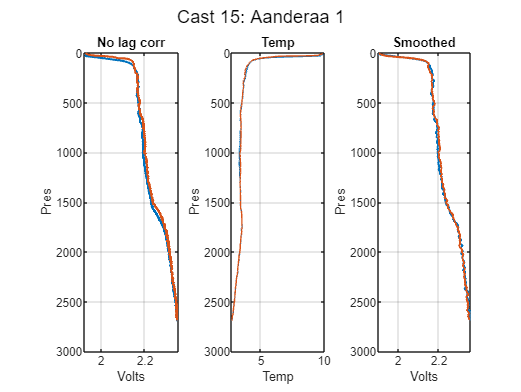

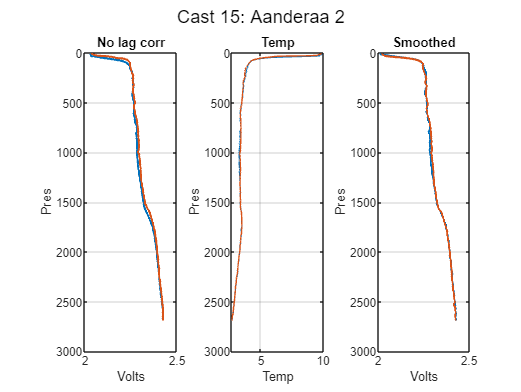

[cast15d, cast15u] = correct_Aanderaa_profiles_Yr7(cast15d,cast15u,tau,'Cast 15');

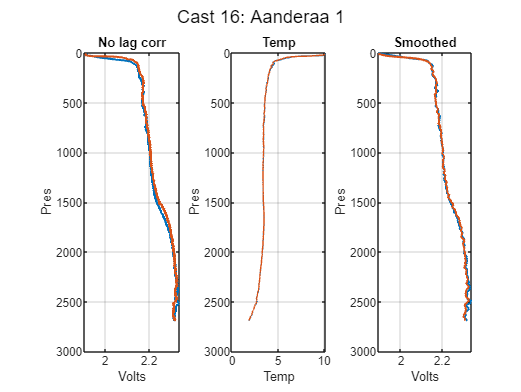

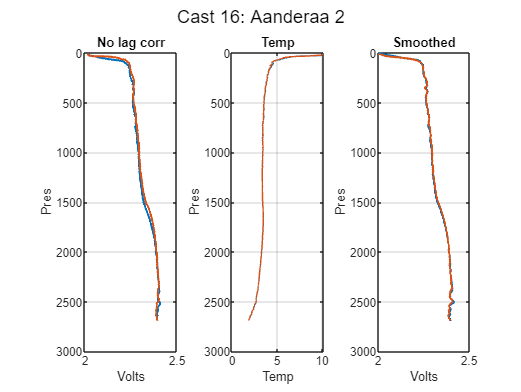

[cast16d, cast16u] = correct_Aanderaa_profiles_Yr7(cast16d,cast16u,tau,'Cast 16');

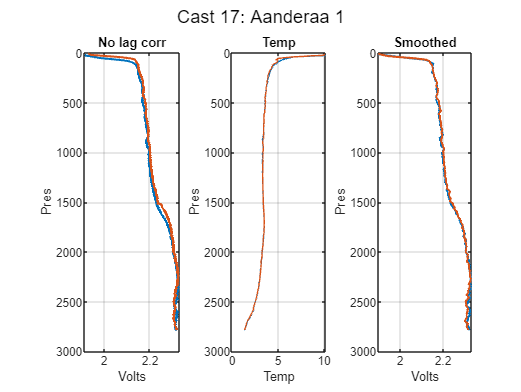

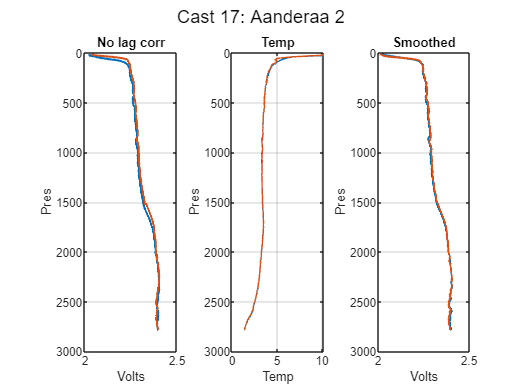

[cast17d, cast17u] = correct_Aanderaa_profiles_Yr7(cast17d,cast17u,tau,'Cast 17');

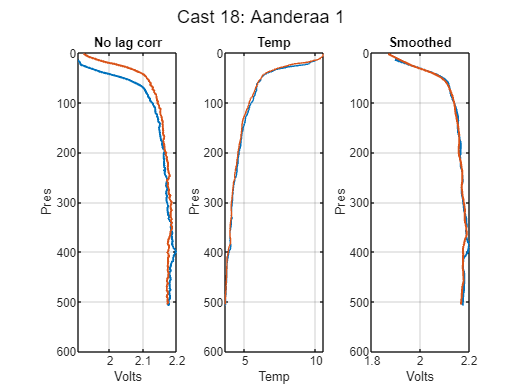

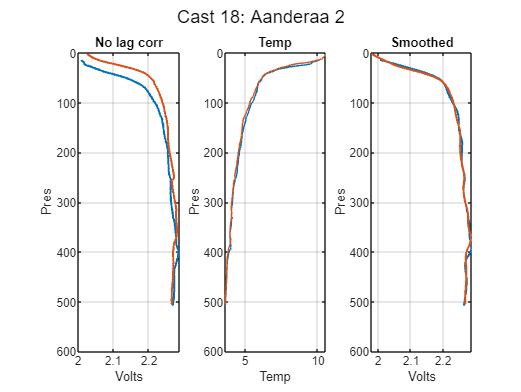

[cast18d, cast18u] = correct_Aanderaa_profiles_Yr7(cast18d,cast18u,tau,'Cast 18');

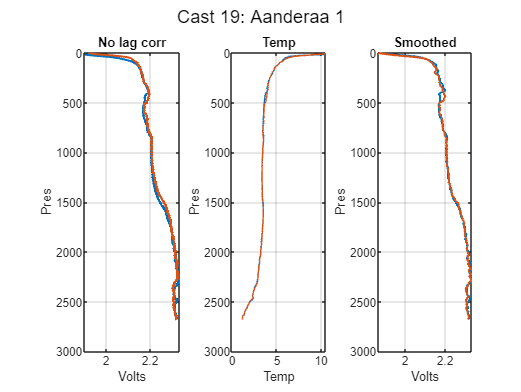

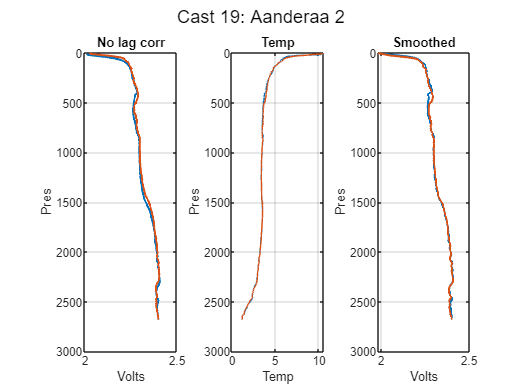

[cast19d, cast19u] = correct_Aanderaa_profiles_Yr7(cast19d,cast19u,tau,'Cast 19');

### Pull out time lag corrected cast data for bottle file/Winkler comparison  (gain correction)

% % From Aanderaa calibration file for SN 502 
% foilcoeff503 = [2.82567E-3 1.20716E-4 2.4593E-6 2.30757E2 -3.09502E-1 -5.60627E1 4.5615E0];
% conccoeff503 = [-1.285961 1.039998];
% salset503 = 0;  % salinity set at 0  
% 
% % From Aanderaa calibration file for SN 377 
% foilcoeff377 = [2.82567E-3 1.20716E-4 2.4593E-6 2.30757E2 -3.09502E-1 -5.60627E1 4.5615E0];
% conccoeff377 = [-1.285961 1.039998];
% salset377 = 0;  % salinity set at 0 

% From Aanderaa calibration file for SN 277 (Voltage Channel == on AR45 
foilcoeff277 = [2.798512E-3	1.179460E-4	2.512907E-6	2.262806E2	-3.570254E-1	-6.104725E1	4.558537E0];
conccoeff277 = [0.000000E+00	1.000000E+00];
salset277 = 0;  % salinity set at 0 


btlgain = [btlsum11.gain; btlsum12.gain; btlsum13.gain];
% btlgaind = [btlsum11.gaind; btlsum12.gaind; btlsum13.gaind];

gain_mean = nanmean(btlgain)

gain_mean = 1.0032

gain_std = nanstd(btlgain)

gain_std = 0.0126


% gaind = nanmean(btlgaind)
% stdd = nanstd(btlgaind)

gain502 = gain_mean;

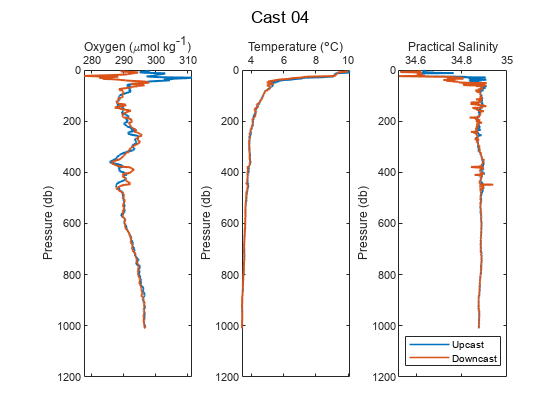

% [castu, castd, btlsum] = Process_Cast_Aanderaa(castu,castd,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast03u, cast03d, btlsum03] = Aanderaa_gain_cast(cast03u,cast03d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 03');
[cast04u, cast04d, btlsum04] = Aanderaa_gain_cast(cast04u,cast04d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 04');

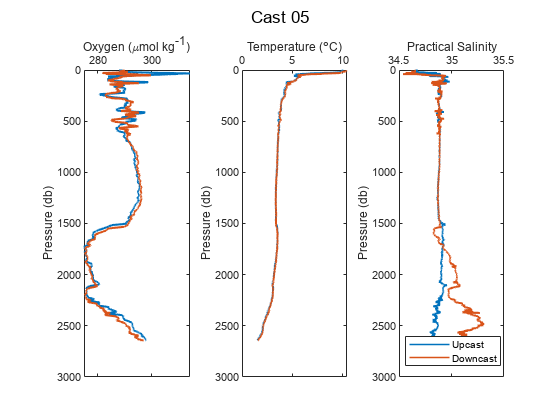

[cast05u, cast05d, btlsum05] = Aanderaa_gain_cast(cast05u,cast05d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 05');

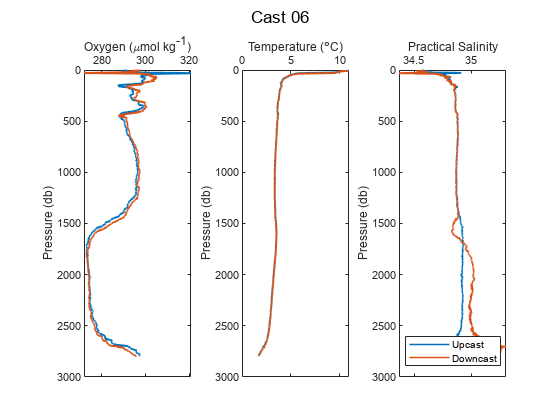

[cast06u, cast06d, btlsum06] = Aanderaa_gain_cast(cast06u,cast06d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 06');

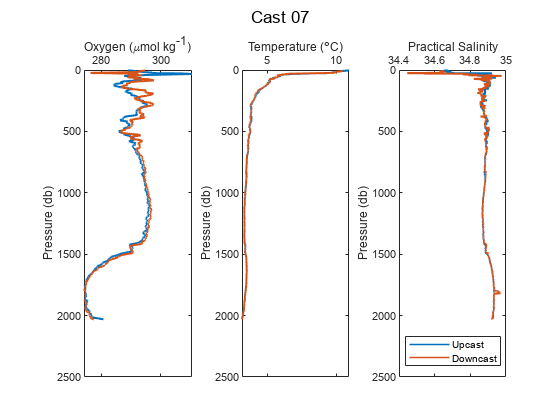

[cast07u, cast07d, btlsum07] = Aanderaa_gain_cast(cast07u,cast07d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 07');

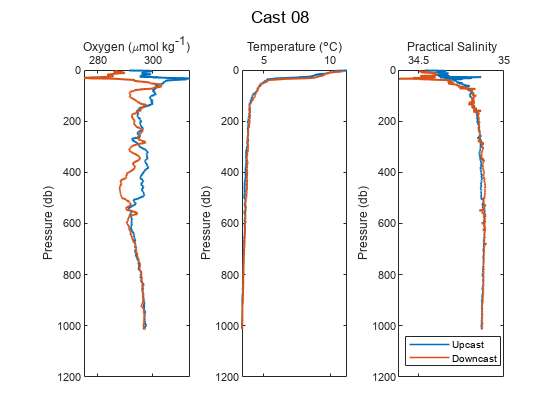

[cast08u, cast08d, btlsum08] = Aanderaa_gain_cast(cast08u,cast08d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 08');

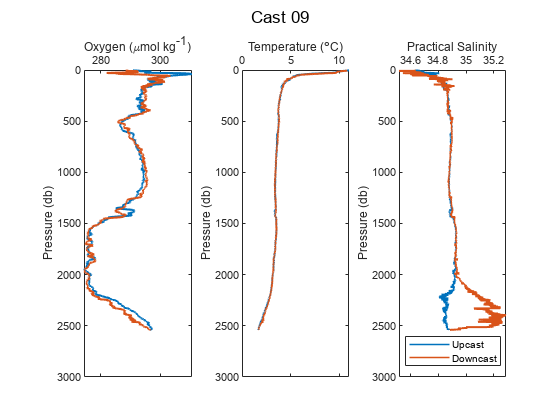

[cast09u, cast09d, btlsum09] = Aanderaa_gain_cast(cast09u,cast09d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 09');

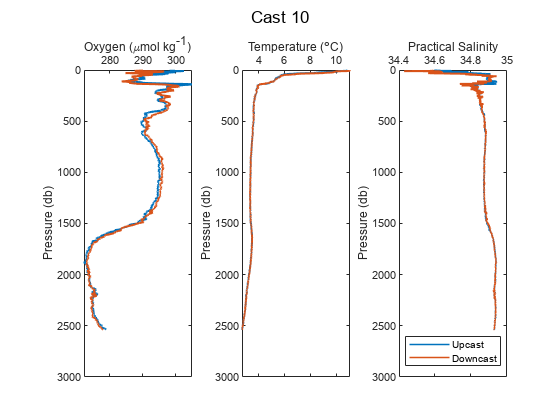

[cast10u, cast10d, btlsum10] = Aanderaa_gain_cast(cast10u,cast10d,0,foilcoeff502,conccoeff502,salset502,gain502,'Cast 10'); 

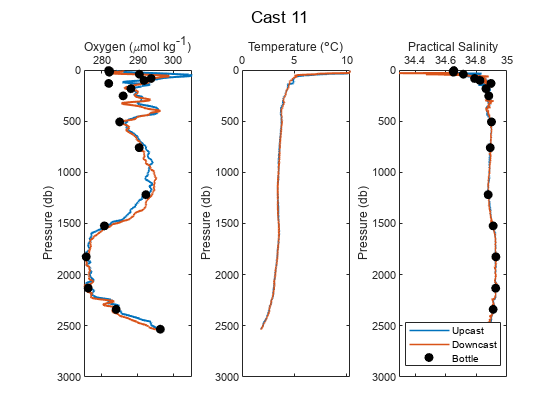

[cast11u, cast11d, btlsum11] = Aanderaa_gain_cast(cast11u,cast11d,btlsum11,foilcoeff502,conccoeff502,salset502,gain502,'Cast 11');

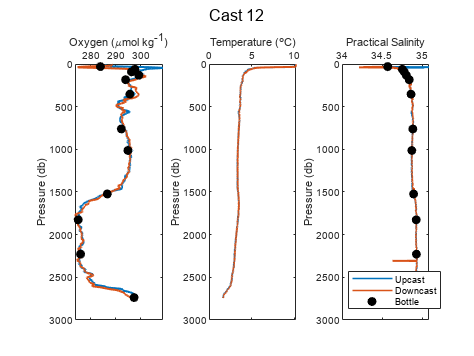

[cast12u, cast12d, btlsum12] = Aanderaa_gain_cast(cast12u,cast12d,btlsum12,foilcoeff502,conccoeff502,salset502,gain502,'Cast 12');

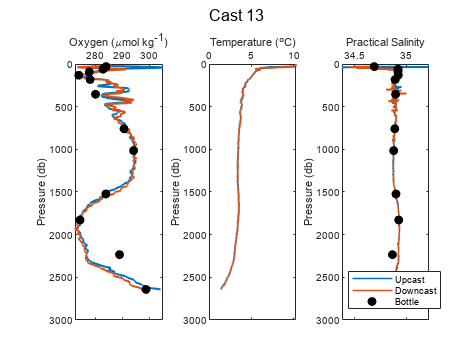

[cast13u, cast13d, btlsum13] = Aanderaa_gain_cast(cast13u,cast13d,btlsum13,foilcoeff502,conccoeff502,salset502,gain502,'Cast 13');

% run('Year6_PT_DO_plots.m')

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year6')
% clear btlsum0
% dt_Processed = datetime;
% save Year6_Processed_KF cast* btl* cal* dt_Processed 